clc;
clear all;

## **Case Study: 6-bus system, 10-phase**

T=10;
N=6;

linedata=[1	2	0.0370 200
1       4       0.0160 200
2	3	0.1015 175
2	4	0.1170 175
3	6	0.0355 175
4	5	0.0370 200
5	6	0.1270 200];
M=size(linedata,1);
H= GSDF(linedata);
fmax=linedata(:,4);

bb= [0;0;0;50;0;0];

d_r=[0 50 50 150 0 75;0 60 90 180 0 70;0 30 90 190 0 72;0 50 40 150 0 77;
    0 69 105 160 0 79;0 24 57 170 0 34;0 56 76 129 0 40;0 60 90 172 0 60;
    0 50 100 176 0 65;0 30 108 134 0 80];  % concerned with T

p_raw=[1.2 0.8 0 0 1.4 1.4;2.8 1.8 0 0 2.4 2.4;4.4 2.8 0 0 2.4 2.4];
q=[0 0 0 0 0 0;-80 -50 0 0 -40 -40;-240 -150 0 0 -40 -40];

gmin=[50;50;0;0;30;25];
gmax=[250;200;0;0;80;100];

ramp_ratio=[0.6;0.7;0;0;0.5;0.6];
UR=gmax.*ramp_ratio;
DR=gmax.*ramp_ratio;

ramp_rate=0.5;
umin=-bb*ramp_rate;
umax=bb*ramp_rate;

***emission infomation***

carbon_tax=0.2;
emission_info=[2 1 0 0 0.5 0.5];
p=p_raw+emission_info*carbon_tax;

**Uncertain Part : At Bus 4 -- wind turbine**

w_loc=[4];
w_num=size(w_loc,1);
real_capacity_scale=20;
w_f= [0 0 0 30 0 0;0 0 0 10 0 0;0 0 0 15 0 0;0 0 0 20 0 0;
    0 0 0 32 0 0;0 0 0 20 0 0;0 0 0 16 0 0;0 0 0 30 0 0;
    0 0 0 10 0 0;0 0 0 20 0 0]; % concerned with T
d_f= d_r-w_f;
filename='.\data\WindGenTotalLoadYTD_2020.xls';
error_data= gen_wind_data(real_capacity_scale,filename);

virtual_bb=[bb bb bb];
real_bb=zeros(N,3);
epsilon=0.1;
gamma=0.4;
if sum(bb)~=0
    for flag=1:3
        for k=1:w_num
            i=w_loc(k);
            virtual_bb(i,flag)= gen_virtual_storage_capacity(bb(i),epsilon,T,gamma,error_data,flag);
        end
        [standard_delta,real_bb(:,flag)]= gen_standard_delta(bb,virtual_bb(:,flag),w_loc);
    end
end

x=zeros(T*N*4,3);
fval=zeros(1,3);
for flag=1:3
    [x(:,flag),fval(:,flag)]=MinC(T,N,M,real_bb(:,flag),d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);
end


Optimal solution found.


Optimal solution found.


Optimal solution found.



**A Clairvoyant Circumstance**

[x_ori,fval_ori]=MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);


Optimal solution found.



error_q=0.01;
exam_MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,x_ori,fval_ori,error_q);

charging decision:
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
   25.0000  -25.0000  -25.0000   25.0000  -25.0000   25.0000   25.0000  -22.0000   -1.0000   -2.0000
         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0

line flow:
  -18.1643  -19.6632  -23.2913  -19.6429    0.4989  -32.3654   -9.6745   -1.5232  -32.6132   -5.9261
   68.1643   69.6632   73.2913   69.6429   49.5011   82.3654   59.6745   51.5232   82.6132   55.9261
   16.7698   39.5919   41.3204   14.6215   50.8872   22.1358   23.1055   30.9493   45.7757   54.5518
   15.0659   15.7449   17.3883   15.7357    6.6116   21.4988

% disp('optimal solution for Chance Constraint:')
% disp(reshape(x(:,1),[],4))
% disp('optimal solution for DRO(Azuma):')
% disp(reshape(x(:,2),[],4))
% disp('optimal solution for DRO(binomial):')
% disp(reshape(x(:,3),[],4))
disp('optimal solution for A Clairvoyant Circumstance')

optimal solution for A Clairvoyant Circumstance


disp(reshape(x_ori,[],4))

   50.0000         0         0   80.0000
  100.0000         0         0  150.0000
         0         0         0         0
         0   25.0000   50.0000         0
   70.0000         0         0  135.0000
  100.0000         0         0  210.0000
   50.0000         0         0   80.0000
  135.0000         0         0  255.0000
         0         0         0         0
         0  -25.0000   25.0000         0
   80.0000         0         0  160.0000
  100.0000         0         0  210.0000
   50.0000         0         0   80.0000
  112.0000         0         0  186.0000
         0         0         0         0
         0  -25.0000         0         0
   80.0000         0         0  160.0000
  100.0000         0         0  210.0000
   50.0000         0         0   80.0000
  100.0000         0         0  150.0000
         0         0         0         0
         0   25.0000   25.0000         0
   80.0000         0         0  160.0000
   92.0000         0         0  190.0000
   50.0000      

G=reshape(x_ori(1:T*N),N,T);
fval_ori_e=emission_info*G*ones(T,1);

disp('the performance for each solution is:')

the performance for each solution is:


disp(fval)

   1.0e+03 *

    6.1828    6.2068    6.1802



disp('the performance for clairvoyant solution is:')

the performance for clairvoyant solution is:


disp(fval_ori)

        6174



% % ramping bind
% ramp_temp=G(:,2:T)-G(:,1:T-1);
% ramp_cap=max(ramp_temp,[],2);
% disp(ramp_cap/gmax)

**Drawing Part**

start=0.1;
ending=0.4;
epsilon_value=start:0.01:ending;
threshold=sqrt(-T*log(start)/2);
gamma_value=ceil(threshold)/T:0.02:(ceil(threshold)+3)/T;
epsilon_size=size(epsilon_value,2);
gamma_size=size(gamma_value,2);

**3 formulations: without discussing distribution**

% fval_all=zeros(epsilon_size,gamma_size,3);
% ramp_rate=0.5;
% for i=1:epsilon_size
%     for j=1:gamma_size
%         epsilon=epsilon_value(i);
%         gamma=gamma_value(j);
%         [~,fval_all(i,j,:)]=gen_performance_for_3_formulations(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%     end
% end

**plot**

% fval_ori_ep_g=fval_ori*ones(1,size(gamma_value,2));
% plot (gamma_value,fval_all(1,:,1),'r',gamma_value,fval_all(1,:,2),'b',gamma_value,fval_all(1,:,3),'g',gamma_value,fval_ori_ep_g,'k--')
% legend('Chance Constraint', 'DRO (Azuma)','DRO (binomial)','clairvoyant')
% ylabel('Performance' )
% xlabel('Coefficient \Gamma')

% fval_ori_ep_e=fval_ori*ones(1,size(epsilon_value,2));
% plot (epsilon_value,fval_all(:,1,1),'r',epsilon_value,fval_all(:,1,2),'b',epsilon_value,fval_all(:,1,3),'g',epsilon_value,fval_ori_ep_g,'k--')
% legend('Chance Constraint', 'DRO (Azuma)','DRO (binomial)','clairvoyant')
% xlim([min(epsilon_value) max(epsilon_value)])
% ylabel('Performance' )
% xlabel('Coefficient \epsilon')

**4 formulations: discussing distribution and emission**

fval_all=zeros(epsilon_size,gamma_size,4);
fval_all_e=zeros(epsilon_size,gamma_size,4);

fval_SSO=zeros(epsilon_size,1);
fval_all_e_SSO=zeros(epsilon_size,1);
ramp_rate=0.5;
for i=1:epsilon_size
    for j=1:gamma_size
        epsilon=epsilon_value(i);
        gamma=gamma_value(j);
        [x_record,fval_all(i,j,:)]=gen_performance_for_4_formulations(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);
        % the emission
        for k=1:4
            G=reshape(x_record(1:T*N,k),N,T);
            fval_all_e(i,j,k)=emission_info*G*ones(T,1);
        end
    end
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal sol

**Benchmark**

c_level=10^(-3);
for i=1:epsilon_size
%     for flag=1:2
        epsilon=epsilon_value(i);
        [fval_SSO(i,1),x_record_SSO]=gen_SSO_average_performance(c_level,epsilon,T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,w_loc,w_num,error_data,ramp_rate,DR,UR);
        G_SSO=reshape(x_record_SSO(1:T*N),N,T);
        fval_all_e_SSO(i,1)=emission_info*G_SSO*ones(T,1);
%     end
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.



## **plot**

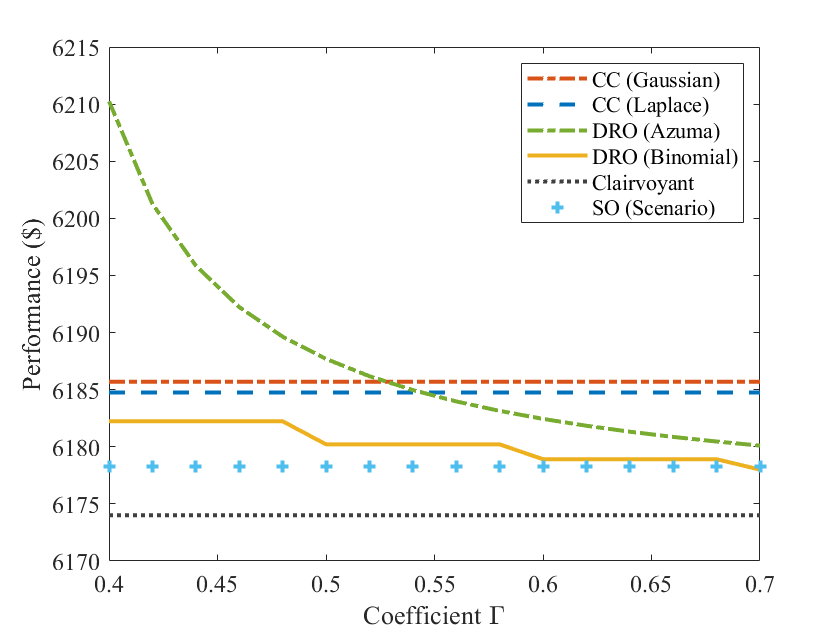

fval_ori_ep_g=fval_ori*ones(1,size(gamma_value,2));
fval_ori_ep_SSO=fval_SSO(1,1)*ones(1,size(gamma_value,2));
figure
plot (gamma_value,fval_all(1,:,1),'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(gamma_value,fval_all(1,:,4),'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(gamma_value,fval_all(1,:,2),'-.','color',[0.4660, 0.6740, 0.1880],'lineWidth',2)
hold on
plot(gamma_value,fval_all(1,:,3),'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(gamma_value,fval_ori_ep_g,':','color',[0.25, 0.25, 0.25],'lineWidth',2)
hold on
plot(gamma_value,fval_ori_ep_SSO,'+','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (Binomial)','Clairvoyant','SO (Scenario)')
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Performance ($)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold' )
xlabel('Coefficient \Gamma','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

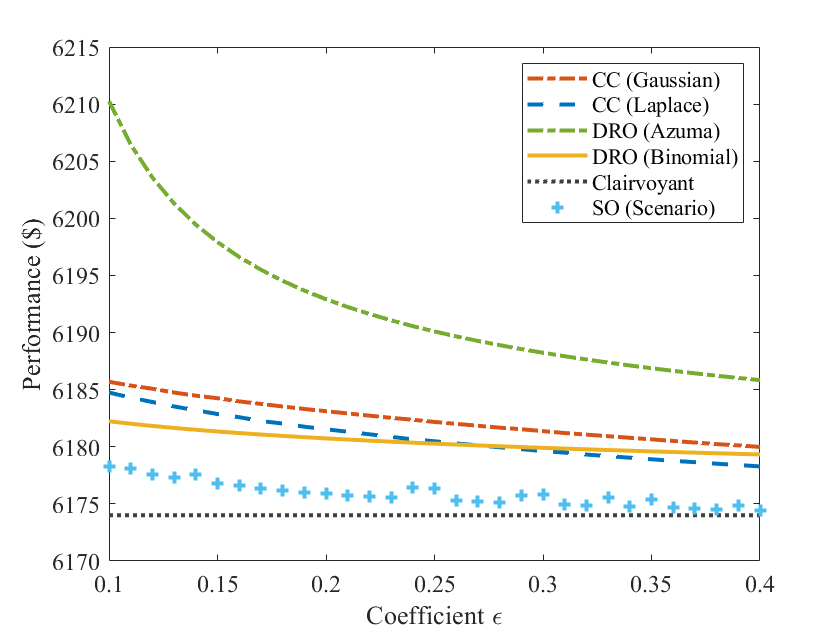

fval_ori_ep_e=fval_ori*ones(1,size(epsilon_value,2));
figure
plot (epsilon_value,fval_all(:,1,1),'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(epsilon_value,fval_all(:,1,4),'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(epsilon_value,fval_all(:,1,2),'-.','color',[0.4660, 0.6740, 0.1880],'lineWidth',2)
hold on
plot(epsilon_value,fval_all(:,1,3),'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(epsilon_value,fval_ori_ep_e,':','color',[0.25, 0.25, 0.25],'lineWidth',2)
hold on
plot(epsilon_value,fval_SSO,'+','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (Binomial)','Clairvoyant','SO (Scenario)')
set(gca,'FontSize',12,'FontName','Times New Roman')
xlim([min(epsilon_value) max(epsilon_value)])
ylabel('Performance ($)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Coefficient \epsilon','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

**Fitting CC and DRO**

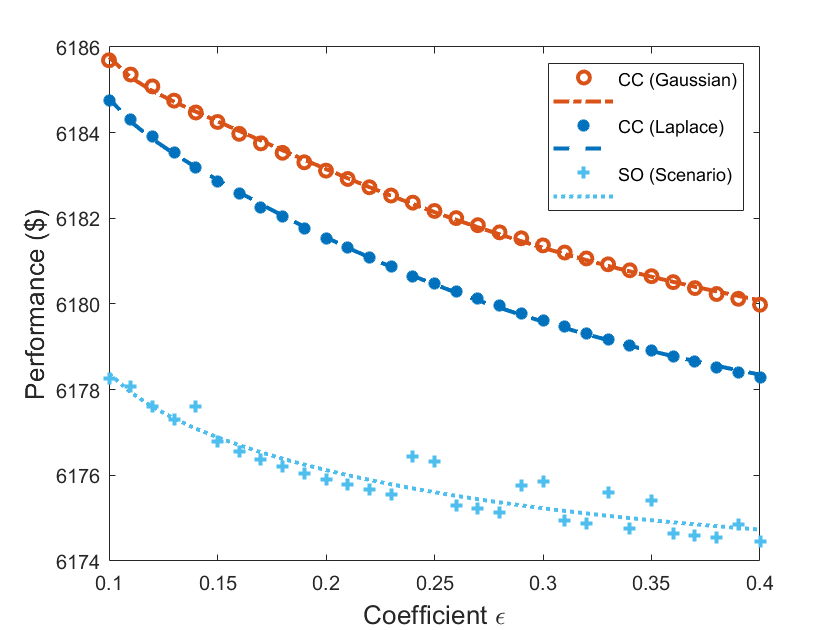

power=1.2;
epsilon_value2=(1./epsilon_value').^power/10;
degree=3;
[p_Gaussian,S_Gaussian]=polyfit(epsilon_value2,fval_all(:,1,1)-fval_ori,degree);
[p_Laplace,S_Laplace]=polyfit(epsilon_value2,fval_all(:,1,4)-fval_ori,degree);
[p_SSO,S_SSO]=polyfit(epsilon_value2,fval_SSO-fval_ori,degree);

% const=0.7;
% epsilon_value2=log(10.*epsilon_value'+const);
% degree=1;
% [p_Gaussian,S_Gaussian]=polyfit(epsilon_value2,fval_all(:,1,1)-fval_all(epsilon_size,1,1),degree);
% [p_Laplace,S_Laplace]=polyfit(epsilon_value2,fval_all(:,1,4)-fval_all(epsilon_size,1,4),degree);
% [p_SSO,S_SSO]=polyfit(epsilon_value2,fval_SSO-fval_SSO(epsilon_size),degree);


y_Gaussian=polyval(p_Gaussian,epsilon_value2)+fval_ori;
y_Laplace=polyval(p_Laplace,epsilon_value2)+fval_ori;
y_SSO=polyval(p_SSO,epsilon_value2)+fval_ori;


figure
plot (epsilon_value,fval_all(:,1,1),'o','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot (epsilon_value,y_Gaussian,'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(epsilon_value,fval_all(:,1,4),'*','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(epsilon_value,y_Laplace,'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(epsilon_value,fval_SSO,'+','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
hold on
plot(epsilon_value,y_SSO,':','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
legend('CC (Gaussian)','','CC (Laplace)', '','SO (Scenario)','')

xlim([min(epsilon_value) max(epsilon_value)])
ylabel('Performance ($)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Coefficient \epsilon','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

**Plot emission**

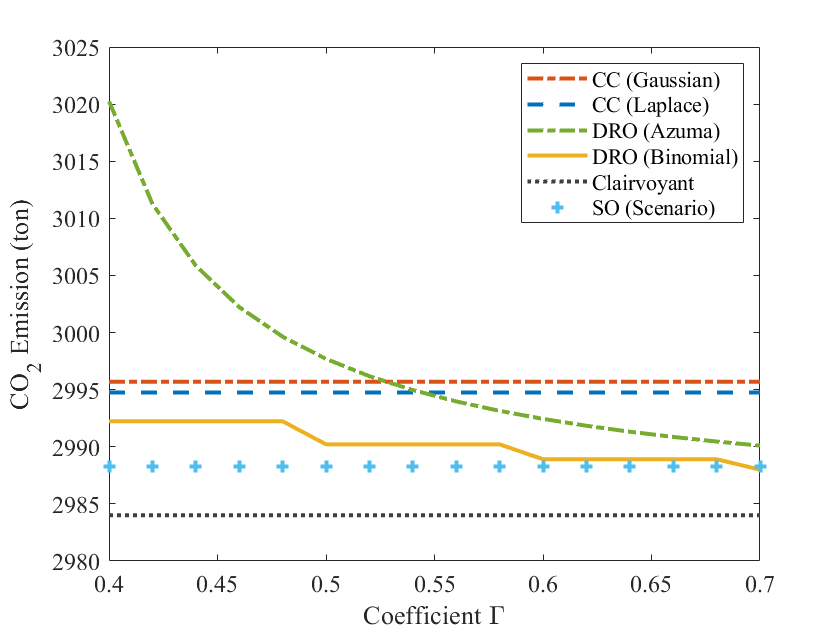

fval_ori_ep_g_e=fval_ori_e*ones(1,size(gamma_value,2));
fval_ori_ep_SSO_e=fval_all_e_SSO(1,1)*ones(1,size(gamma_value,2));
figure
plot (gamma_value,fval_all_e(1,:,1),'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(gamma_value,fval_all_e(1,:,4),'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(gamma_value,fval_all_e(1,:,2),'-.','color',[0.4660, 0.6740, 0.1880],'lineWidth',2)
hold on
plot(gamma_value,fval_all_e(1,:,3),'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(gamma_value,fval_ori_ep_g_e,':','color',[0.25, 0.25, 0.25],'lineWidth',2)
hold on
plot(gamma_value,fval_ori_ep_SSO_e,'+','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (Binomial)','Clairvoyant','SO (Scenario)')
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('CO_2 Emission (ton)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold' )
xlabel('Coefficient \Gamma','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

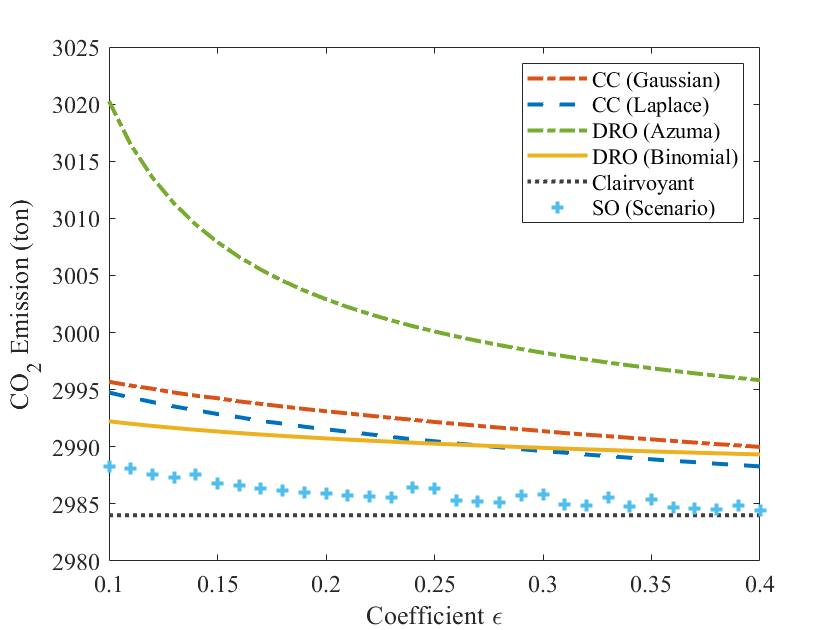

fval_ori_ep_e_e=fval_ori_e*ones(1,size(epsilon_value,2));
figure
plot (epsilon_value,fval_all_e(:,1,1),'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(epsilon_value,fval_all_e(:,1,4),'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(epsilon_value,fval_all_e(:,1,2),'-.','color',[0.4660, 0.6740, 0.1880],'lineWidth',2)
hold on
plot(epsilon_value,fval_all_e(:,1,3),'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(epsilon_value,fval_ori_ep_e_e,':','color',[0.25, 0.25, 0.25],'lineWidth',2)
hold on
plot(epsilon_value,fval_all_e_SSO,'+','color',[0.3010, 0.7450, 0.9330],'lineWidth',2)
legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (Binomial)','Clairvoyant','SO (Scenario)')
set(gca,'FontSize',12,'FontName','Times New Roman')
xlim([min(epsilon_value) max(epsilon_value)])
ylabel('CO_2 Emission (ton)' ,'FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Coefficient \epsilon','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

**Computation Time**

% % CC(Gaussian)
% tStart = cputime;
% gen_performance_CC_Gaussian(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
% t_CC= cputime - tStart;
% % DRO(Azuma)
% tStart = cputime;
% gen_performance_DRO_Azuma(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
% t_DRO= cputime - tStart;
% %clairvoyant
% tStart = cputime;
% MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax);
% t_ori= cputime - tStart;
% % SSO
% tStart = cputime;
% gen_SSO_average_performance(c_level,epsilon,T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,w_loc,w_num,error_data,ramp_rate);
% t_SSO= cputime - tStart;
% % barplot
% bar([t_CC,t_DRO,t_ori,t_SSO])

**The influence of storage on the spot**

epsilon=0.1;
gamma=0.4;
size_range=0:2:160;
new_bb=zeros(N,1);
fval_storage_size=zeros(size(size_range,2),4);
fval_storage_size_ori=zeros(size(size_range,2),1);
for iter=1:size(size_range,2)
    size_value=size_range(iter);
    for i=1:w_num
        k=w_loc(i);
        new_bb(k,1)=size_value;
    end
    ramp_rate=0.5;
    new_umin=-new_bb./2;
    new_umax=new_bb./2;
    [~,fval_storage_size(iter,:)]=gen_performance_for_4_formulations(T,N,M,new_bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);
    [~,fval_storage_size_ori(iter,:)]=MinC(T,N,M,new_bb,d_f,p,q,H,fmax,gmin,gmax,new_umin,new_umax,DR,UR);
end


Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.




Optimal solution found.


Optimal solution found.


Optimal solution found.


Optimal solution found.




Optimal solution found.



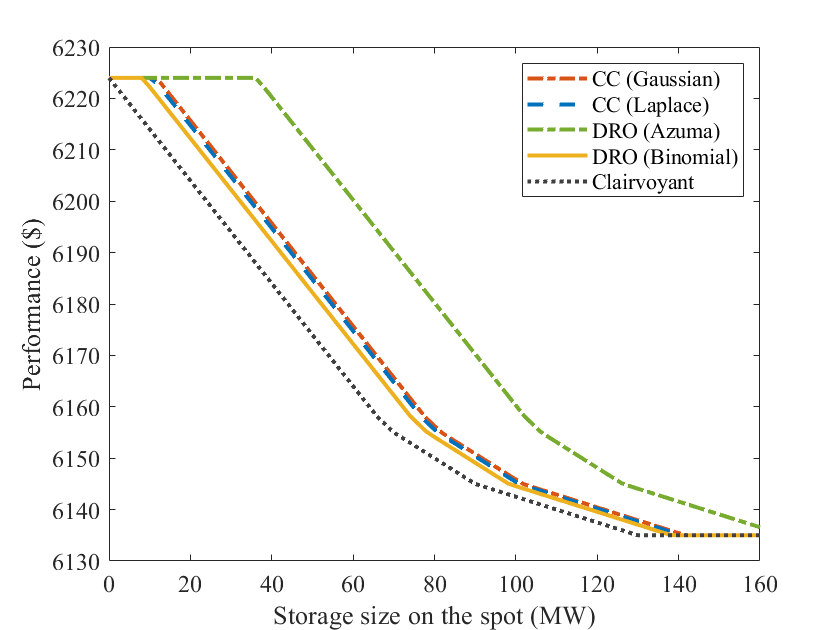

figure
plot (size_range,fval_storage_size(:,1),'-.','color',[0.8500, 0.3250, 0.0980],'lineWidth',2)
hold on
plot(size_range,fval_storage_size(:,4),'--','color',[0, 0.4470, 0.7410],'lineWidth',2)
hold on
plot(size_range,fval_storage_size(:,2),'-.','color',[0.466970729970799707970709790, 0.6740, 0.1880],'lineWidth',2)
hold on
plot(size_range,fval_storage_size(:,3),'-','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(size_range,fval_storage_size_ori,':','color',[0.25, 0.25, 0.25],'lineWidth',2)
legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (Binomial)','Clairvoyant')
xlim([min(size_range) max(size_range)])
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Performance ($)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold' )
xlabel('Storage size on the spot (MW)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

**Considering distributions**

% epsilon=0.1;
% gamma=0.4;
% size_range=0:2:160;
% new_bb=zeros(N,1);
% fval_storage_size=zeros(size(size_range,2),4);
% fval_storage_size_ori=zeros(size(size_range,2),1);
% for iter=1:size(size_range,2)
%     size_value=size_range(iter);
%     for i=1:w_num
%         k=w_loc(i);
%         new_bb(k,1)=size_value;
%     end
%     ramp_rate=0.5;
%     new_umin=-new_bb./2;
%     new_umax=new_bb./2;
%     [~,fval_storage_size(iter,:)]=gen_performance_for_4_formulations(T,N,M,new_bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%     [~,fval_storage_size_ori(iter,:)]=MinC(T,N,M,new_bb,d_f,p,q,H,fmax,gmin,gmax,new_umin,new_umax);
% end
% plot (size_range,fval_storage_size(:,1),'r',size_range,fval_storage_size(:,4),'y',size_range,fval_storage_size(:,2),'b',size_range,fval_storage_size(:,3),'g',size_range,fval_storage_size_ori,'k--')
% legend('CC (Gaussian)','CC (Laplace)', 'DRO (Azuma)','DRO (binomial)','clairvoyant')
% xlim([min(size_range) max(size_range)])
% ylabel('Performance' )
% xlabel('Coefficient: storage size on the spot')

**The influence of storage of other places (controlling variables)**

% error_q=0.01;
% epsilon=0.1;
% gamma=0.4;
% loc_range=1:N;
% for i=1:w_num
%         k=w_loc(i);
%         loc_range(find(loc_range==k))=[];
% end
% 
% fval_storage_size_2=zeros(size(loc_range,2),3);
% fval_storage_size_ori_2=zeros(size(loc_range,2),1);
% x_study_loc=zeros(4*N*T,size(loc_range,2));
% for iter=1:size(loc_range,2)
%     new_bb_2=zeros(N,1);
%     loc=loc_range(iter);
%     new_bb_2(loc,1)=10;
%     for i=1:w_num
%         k=w_loc(i);
%         new_bb_2(k,1)=14; % not saturated
%     end
%     umin_2=-new_bb_2./2;
%     umax_2=new_bb_2./2;
%     ramp_rate=0.5;
%     [~,fval_storage_size_2(iter,:)]=gen_performance_for_3_formulations(T,N,M,new_bb_2,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%     [x_study_loc(:,iter),fval_storage_size_ori_2(iter,:)]=MinC(T,N,M,new_bb_2,d_f,p,q,H,fmax,gmin,gmax,umin_2,umax_2);
%     % disp(reshape(x,[],4))
% %     exam_MinC(T,N,M,new_bb_2,d_f,p,q,H,fmax,gmin,gmax,umin,umax,x,fval_storage_size_ori_2(iter,:),error_q);
% end
% plot(loc_range,fval_storage_size_2(:,1),'+',loc_range,fval_storage_size_2(:,2),'o',loc_range,fval_storage_size_2(:,3),'*',loc_range,fval_storage_size_ori_2,'s')
% legend('Chance Constraint', 'DRO (Azuma)','DRO (binomial)','clairvoyant')
% xlim([min(loc_range)-1 max(loc_range)+1])
% ylabel('Performance' )
% xlabel('Coefficient: storage location')

**Conparison study on the node of interest: node 3 vs others**

% x_interest=x_study_loc(:,3);
% G_interest=reshape(x_interest(1:T*N),N,T);
% U_interest=reshape(x_interest(T*N+1:2*T*N),N,T);
% Expense_interest=reshape(x_interest(3*T*N+1:4*T*N),N,T);
% D=d_f.';
% disp('Generation: ')
% disp(G_interest.')
% disp('Storage:')
% disp(U_interest.')
% disp('line flow:');
% disp(H*(G_interest-U_interest-D))
% disp('expense')
% disp(Expense_interest.')
% disp('Generator 2 expense:')
% disp(sum(Expense_interest(2,:)))
% disp('Generator 5 & 6 expense:')
% disp(sum(Expense_interest(5,:))+sum(Expense_interest(6,:)))

% x_interest=x_study_loc(:,2);
% G_interest=reshape(x_interest(1:T*N),N,T);
% U_interest=reshape(x_interest(T*N+1:2*T*N),N,T);
% Expense_interest=reshape(x_interest(3*T*N+1:4*T*N),N,T);
% D=d_f.';
% disp('Generation: ')
% disp(G_interest.')
% disp('Storage:')
% disp(U_interest.')
% disp('line flow:');
% disp(H*(G_interest-U_interest-D))
% disp('expense')
% disp(Expense_interest.')
% disp('Generator 2 expense:')
% disp(sum(Expense_interest(2,:)))
% disp('Generator 5 & 6 expense:')
% disp(sum(Expense_interest(5,:))+sum(Expense_interest(6,:)))

The comparison results tell us:

 the saved expense are from Generator 2. While the gen 2 is expensive than gen 5& gen 6, but it must be put into use since gen 3 and gen 4 have a maximum capacity. Let generator be allowed to save some expense, more energy are from 5&6. 

But why gen 2 must be taken into use if there are no storage on load 3? Is it because line capacity? Is it because  gen 5&6 have a maximum capacity

TO be more specific, why gen 3&4 are not full, the system still choose to use gen 2 when there is no storage?  because (for t=4, t=6):

% g_hypothetical=[ 50.0000  94.0000         0         0   80.0000  100.0000].';
% c_hypothetical=[ 1.6*50.0000  2*94.0000-50         0         0   2.5*80.0000-40  2.5*100.0000-40].';
% disp('hypothetical:')
% disp(sum(c_hypothetical))
% disp('actual (our optimal solution):')
% disp(sum(Expense_interest(:,4)))
% % d_4=d_f(4,:).';
% % u_4=U_interest(:,4);
% % disp(H*(g_hypothetical-d_4-u_4))
% new_bb_h=zeros(N,1);
% new_bb_h(2,1)=10;
% for i=1:w_num
%     k=w_loc(i);
%     new_bb_h(k,1)=14; % not saturated
% end
% x_hypothetical=x_study_loc(:,2);
% x_hypothetical(3*N+1:4*N)=g_hypothetical;
% x_hypothetical(3*N*T+3*N+1:3*N*T+4*N)=c_hypothetical;
% exam_MinC(T,N,M,new_bb_h,d_f,p,q,H,fmax,gmin,gmax,umin,umax,x_hypothetical,fval_storage_size_ori_2(2,:),error_q);

because dispatch gen 2 is actually cheaper!

So nothing concerns line capacity? The real difference:

% disp('Generation difference')
% disp((reshape(x_study_loc(1:T*N,3),N,T)-reshape(x_study_loc(1:T*N,2),N,T)).')
% disp('storage difference')
% disp((reshape(x_study_loc(N*T+1:N*T+T*N,3),N,T)-reshape(x_study_loc(N*T+1:N*T+T*N,2),N,T)).')

why gen 2 gets to produce less with storage?!!! and why it has to be specific at location of no generation!